# 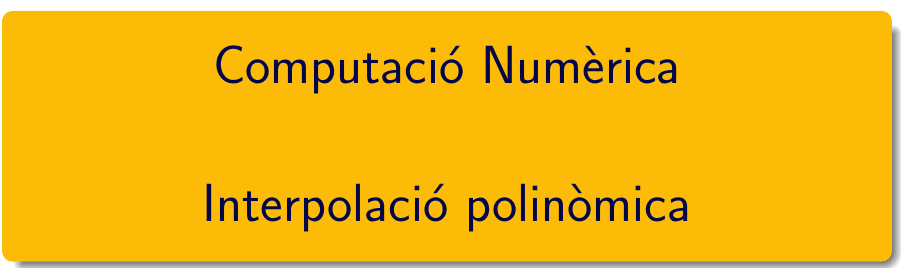

================================================================================

# Pràctica 6 - Interpolació polinònimca i ajust de dades (I)

`document preparat per M. Àngela Grau Gotés - març 2023`

## $\bullet$APRENEM .....Bloc1

### Polinomis i MATLAB®

Consulteu la pàgina [crear y evaluar polinomios](https://es.mathworks.com/help/matlab/math/create-and-evaluate-polynomials.html) y la pàgina [Raíces de polinomios](https://es.mathworks.com/help/matlab/ref/roots.html), ambdues de la documentació de MATLAB®. També us pot interesar la pàgina [Integrar y diferenciar polinomios](https://es.mathworks.com/help/matlab/math/integrate-and-differentiate-polynomials.html).

Després de llegir els dos primers documents, calculeu:

- les arrels del polinomi cúbic (grau 3)  $x^3+4x^2+4x=0$ 

- avalueu el polinomi  $x^5-1$ per $x=2$

- coficients del polinomi d'arrels els enters  -5,-2, -1, 1, 2, i 8. Quin grau té?

p = [1 4 4 0];          % vector amb els coeficients del polinomi en ordre descendent

r =      0
    -2
    -2


r = roots(p)            % arrels
p = [1 0 0 0 0 -1];                % vector amb els coeficients del polinomi 

p_2 = 31

p_2 = polyval(p,2)                % valor polinomi

r =   -0.8090 + 0.5878i
  -0.8090 - 0.5878i
   0.3090 + 0.9511i
   0.3090 - 0.9511i
   1.0000 + 0.0000i


r = roots(p)                                % vector amb les arrels

p =     1.0000   -0.0000    0.0000    0.0000   -0.0000   -1.0000


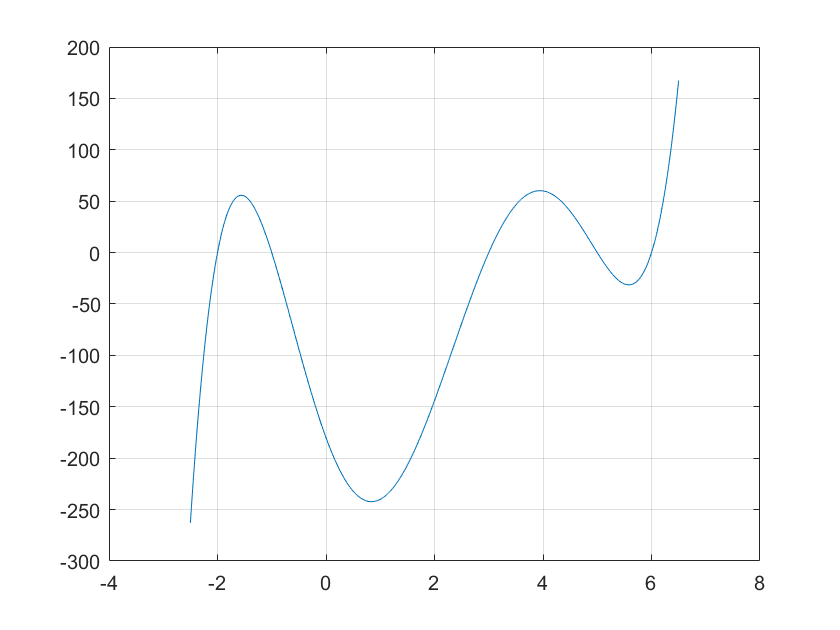

p = poly(r)                        % coeficients polinomi d'arrels r
% un polinomi random
arrels = [6 5 3 -2 -1];
f = poly(arrels);
x = linspace(-2.5,6.5,500);
plot(x, polyval(f,x))

grid on;

### Polinomi interpolador (matriu de Vandermonde)

Els coeficients del polinomi interpolador s'obtenen resolent el sistema lineal corresponent: amb matriu del sistema la matriu de Vandermonde.

x = 1:6;
y = [16 18 21 17 15 12];    % amb 6 dades, puc construir un polinomi interpoladors de grau 5
plot(x,y,'*')
 

V =            1           1           1           1           1           1
          32          16           8           4           2           1
         243          81          27           9           3           1
        1024         256          64          16           4           1
        3125         625         125          25           5           1
        7776        1296         216          36           6           1


V = vander(x)

coef =    -0.2417
    4.3333
  -28.9583
   87.6667
 -115.8000
   69.0000


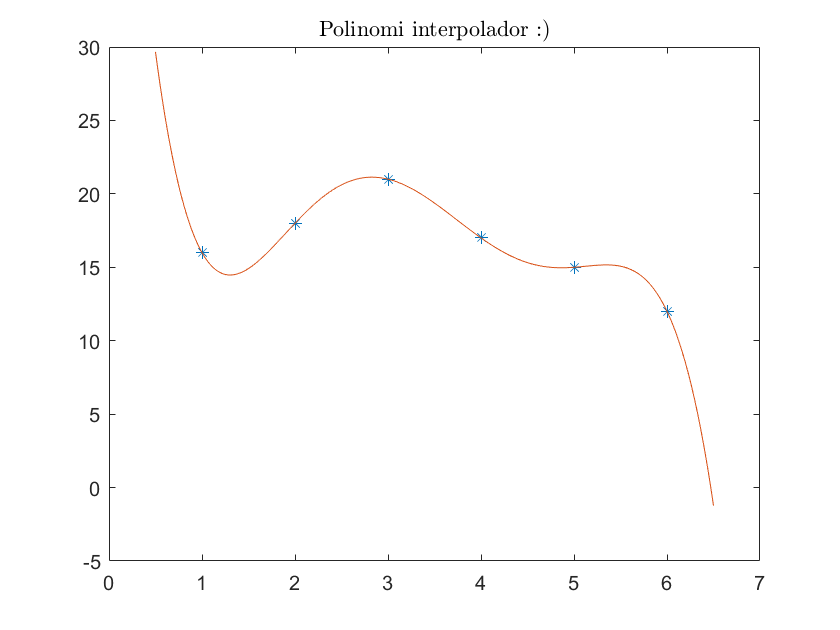

coef = V\y'     %coeficients del polinomi interpolador
hold on; 
x = linspace(0.5,6.5,500);
plot(x, polyval(coef,x))
title("Polinomi interpolador :)", 'Interpreter','latex')

hold off

Això no és el mateix que fa polyfit. Polyfit dona el polinomi que s'ajusta a les dades per mínims quadrats. Si s'utilitza per trobar el polinomi interpolador, s'ha d'utilitzar amb el grau concret del polinomi, és a dir, polyfit(x,y,y.length()-1)

### Polinomi interpolador (fórmula de Lagrange)

Baixeu-vos del campus el codi de polyinterp.m. Aquest codi és el que C. Moler explica en el chapter 3 dels seus apunts *"*[*Numerical Computing with Matlab*](https://www.mathworks.com/moler/chapters.html)*". *

x = [0,1,2,3];
y = [-5 -6 -1 16];

u =          0    0.0060    0.0120    0.0180    0.0240    0.0301    0.0361    0.0421    0.0481    0.0541    0.0601    0.0661    0.0721    0.0782    0.0842    0.0902    0.0962    0.1022    0.1082    0.1142    0.1202    0.1263    0.1323    0.1383    0.1443    0.1503    0.1563    0.1623    0.1683    0.1743    0.1804    0.1864    0.1924    0.1984    0.2044    0.2104    0.2164    0.2224    0.2285    0.2345    0.2405    0.2465    0.2525    0.2585    0.2645    0.2705    0.2766    0.2826    0.2886    0.2946


u = linspace(0,3,500)

fu =    -5.0000   -5.0120   -5.0240   -5.0361   -5.0481   -5.0601   -5.0721   -5.0841   -5.0961   -5.1081   -5.1200   -5.1320   -5.1439   -5.1558   -5.1677   -5.1796   -5.1915   -5.2033   -5.2152   -5.2270   -5.2387   -5.2505   -5.2622   -5.2739   -5.2856   -5.2972   -5.3088   -5.3204   -5.3319   -5.3434   -5.3549   -5.3663   -5.3776   -5.3890   -5.4003   -5.4115   -5.4227   -5.4339   -5.4450   -5.4560   -5.4671   -5.4780   -5.4889   -5.4998   -5.5105   -5.5213   -5.5320   -5.5426   -5.5531   -5.5636


fu = polyinterp(x,y,u)       %retornara els valors del polinomi interpolador evaluat en u
%plot(u,fu)

% Polinomi en symbolic
syms s; 

$$p(s) = \frac{s\,\left(s-1\right)\,\left(s-3\right)}{2}+5\,\left(\frac{s}{2}-1\right)\,\left(\frac{s}{3}-1\right)\,\left(s-1\right)+\frac{16\,s\,\left(\frac{s}{2}-\frac{1}{2}\right)\,\left(s-2\right)}{3}-6\,s\,\left(\frac{s}{2}-\frac{3}{2}\right)\,\left(s-2\right)$$

p(s) = polyinterp(x,y,s)

$$p(s) = s^{3}-2\,s-5$$

p(s) = simplify(p(s))

p_2 = -1

p_2 = double(p(2))

x =      0     1     2     4     8


La rutina polyinterp.m s'obtenen els valors del polinomi interpolador a la taula [x;y] i permet fer la seva representació gràfica. En cap cas obtenim els coeficients del polinomi interpolador. 

`Exemple 1`` - Llista de problemes, exercici 1`. 

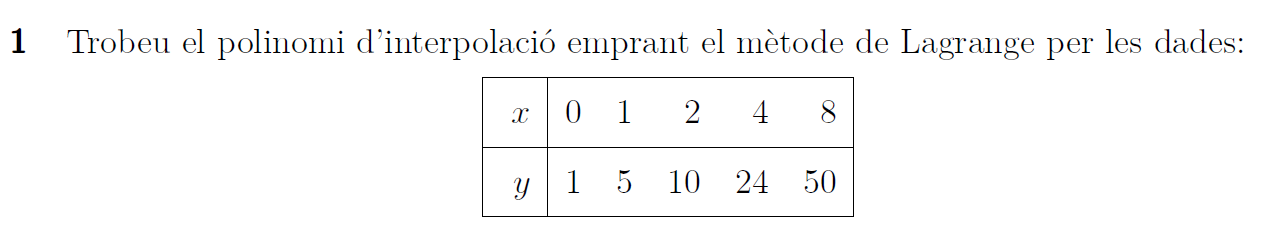

 x = [0 1 2 4 8]

y =      1     5    10    24    50


 y = [1 5 10 24 50]
 

### Polinomi interpolador (diferències dividides de Newton)

`Exemple 2`` - Llista de problemes, exercici 2`. 

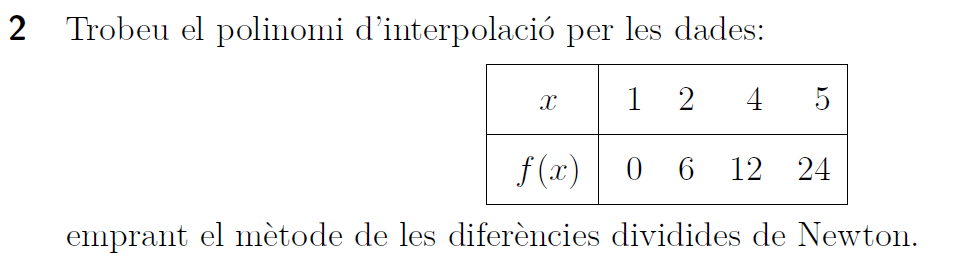

Baixeu-vos el codi de MATLAB fileEchange [codi diferències dividides](https://es.mathworks.com/matlabcentral/fileexchange/105325-matlab-functions-for-numerical-interpolation-methods)

clearvars
x = [1 2 4 5];
y = [0 6 12 24];

L =      0     6    -1     1
     6     3     3     0
    12    12     0     0
    24     0     0     0


sol = 8

[L,sol] = fNewtonDDI(x,y,3)     % divided diferences Newton

### Funció de MATLAB®

Els coeficients del polinomi interpolador es poden obtenir amb polyfit, i els valors aproximats amb polyval. Consulteu [polyfit](https://es.mathworks.com/help/matlab/ref/polyfit.html)

`Exemple 3`` - Canvi d'escala` 

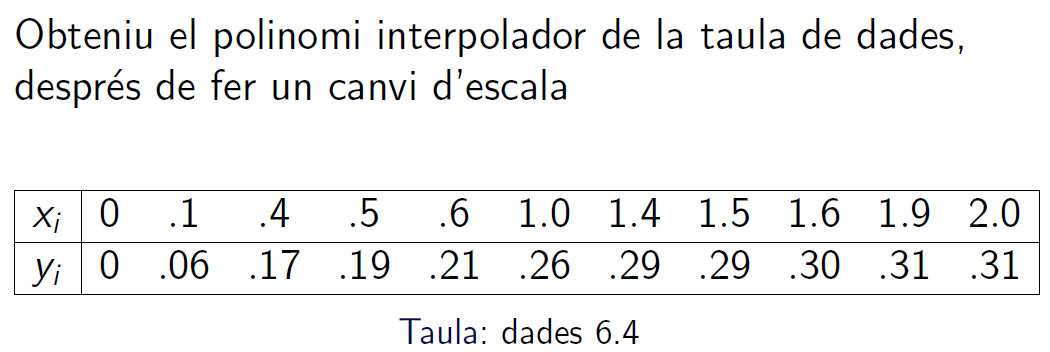

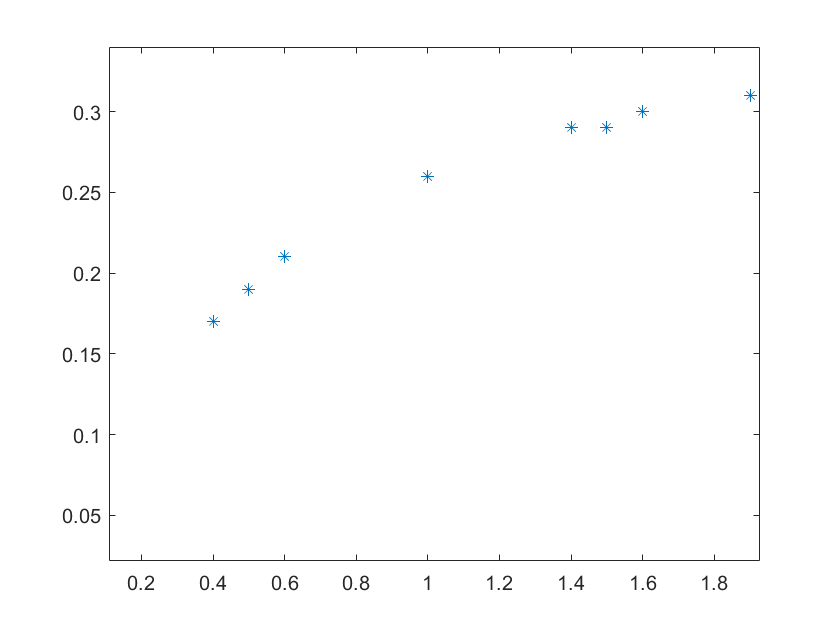

x = [0 .1 .4 .5 .6 1.0 1.4 1.5 1.6 1.9 2.0];
y = [0 .06 .17 .19 .21 .26 .29 .29 .30 .31 .31];

plot(x,y, '*') %Si cliquem obrir el plot --> tools --> basic fitting
%xlim([0.11 1.93])
%ylim([0.022 0.340])

`OBSERVACIÓ - polyinterp de Moler = polyfit + polyval de MATLAB`

## $\bullet$PRACTIQUEM ....

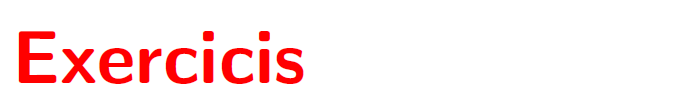

### Exercici 1

Aquest exercici s'ha de resoldre fent ús de polinomis de Lagrange,  **polyinterp**

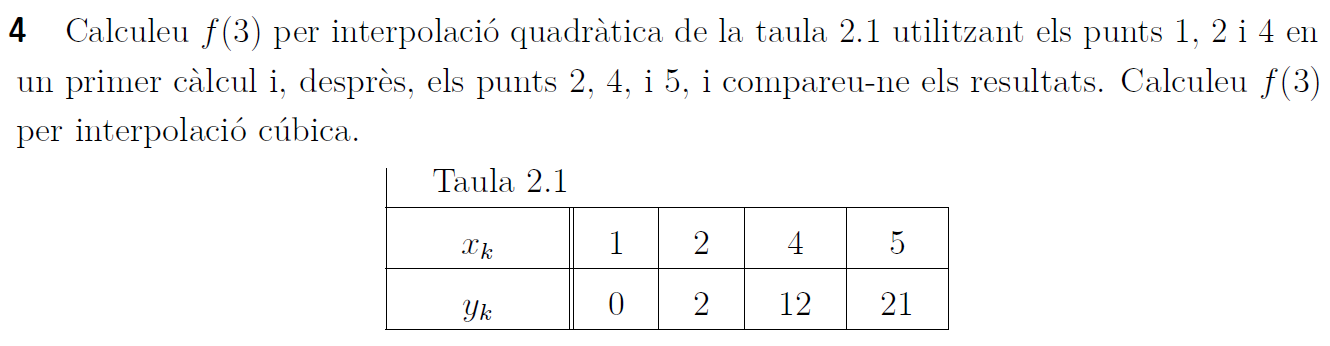

clearvars
x = [1 2 4 5]; y = [0 2 12 21];

- primer càlcul

x1=x(1:3);  y1=y(1:3)
valor = polyinterp(x1,y1,3);
disp(['valor1 =',num2str(valor)])

- segon  càlcul

- tercer  càlcul

### Exercici 2

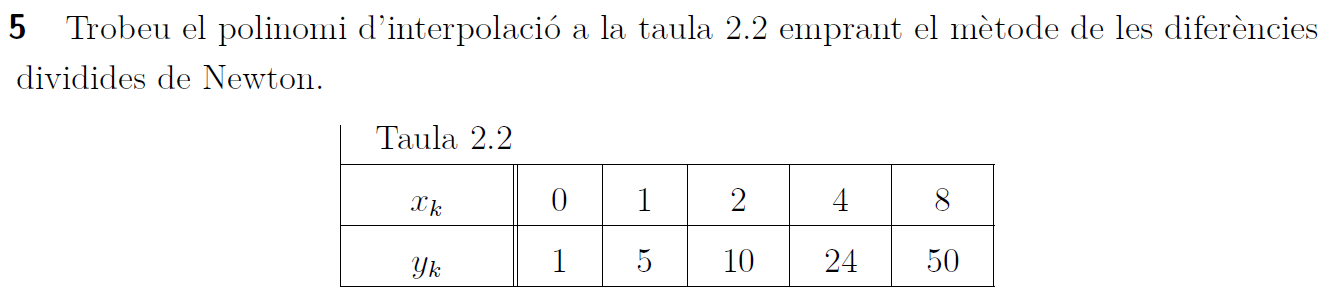

clearvars; clf
x = [0 1 2 4 8]; y = [0,5 10 24 50];
disp([x; y])
 

### Exercici 3

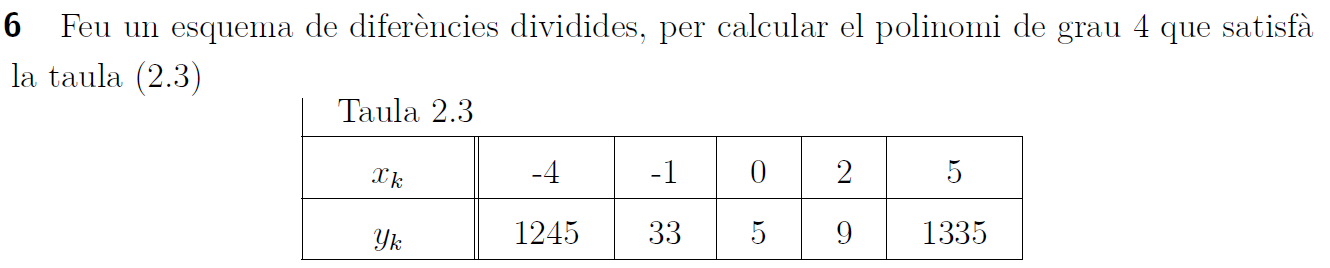

clearvars; clf
x = [-4 -1 0 2 5]; y = [1245 33 5 9 1335];
disp([x; y])


### Exercici 4. Interpolació inversa

Aplicació de la interpolació al càlcul de zeros de funcions (`Interpolació inversa`)

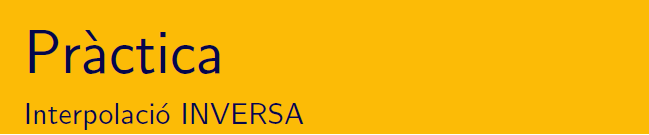

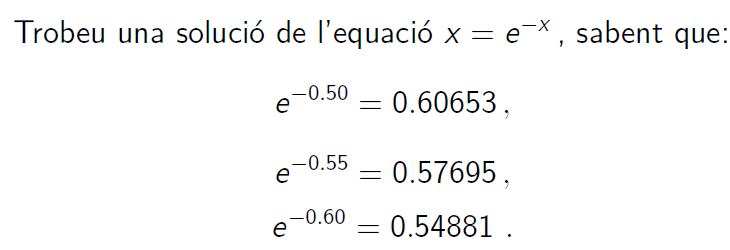


x = [0.5:0.05:0.6];
y = x-exp(-x);

    0.5000   -0.1065
    0.5500   -0.0269
    0.6000    0.0512



disp([x; y]')
% x = e^{-1}
% f(x) = x - e^{-1}
% y = f^{-1}(x)
% Volem trobar el candidat a arrel

root = 0.5671

root = polyinterp(y,x,0)

tol = 3.3969e-07

tol = root - exp(-root)

### Exercici 5. Comportament de l'error en la interpolació polinòmica

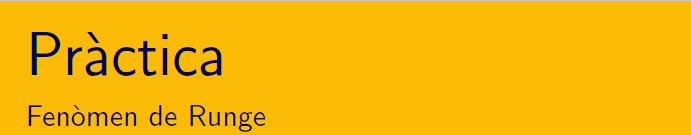

Baixeu-vos del campus el codi de rungeinterp.m. Aquest codi és el que C. Moler explica en el chapter 3 dels seus apunts *"Numerical Computing with Matlab". *Consulteu l'exercici 3.9 de la pàgina 23. Enllaç blog Cleve Moler [Explore Runge’s Polynomial Interpolation Phenomenon](https://blogs.mathworks.com/cleve/2018/12/10/explore-runges-polynomial-interpolation-phenomenon/)

a) Experimenteu la interpolació de la funció f(x) per n=2,3,7,11,13,17,19,23,29 ... o altres valors en punts equiespaiats fent ús de rungeinterp.m i polyinterp.m

 % rungeinterp()

Responeu: Per a quins x de l'interval [-1,1] és compleix $P_n(x) \rightarrow f(x)$ per $n \rightarrow \infty$?

b) Experimenteu la interpolació de la funció f(x) per n=2,3,7,11,13,17,19,23,29 ... o altres valors fent en punts no EQUIESPAIATS fent ús de interp_gadget.m i polyinterp.m

Responeu: Per a quin tipus d'abscises és compleix $P_n(x) \rightarrow f(x)$ per $n \rightarrow \infty$ per a tot x de l'interval [-1,1] ?

## $\bullet$APRENEM ..... Bloc 2

### Interpolació polinomial a trossos. 

clearvars; 
x = 1:6;
y = [16 18 21 17 15 12];
interpgui(x,y)

Unrecognized function or variable 'interpgui'.

**Diferències entre spline i pchip**

clearvars;
x = 1: 8;
y = zeros (1,8);
y (4) = 1;
interpgui(x, y)

### Funció de MATLAB® 

Per veure totes les possibilitats d'interpolació en MATLAB® consulteu la pàgina [interpolación](https://es.mathworks.com/help/matlab/interpolation.html) y més concretament la pàgina de la comanda [interp1](https://es.mathworks.com/help/matlab/ref/interp1.html), per obtenir un polinomi interpolador a trossos. Resum de de la comanda. 

Baixeu-vos del campus ***InterpolationofCoarselySampledSineFunctionExample.mlx, ***és el primer exemple de la documentació. Apreneu com s'usa la comanda interp1 per a obtenir els valors de l'spline lineal i els valors de l'spline cúbic. 

% openExample('matlab/InterpolationofCoarselySampledSineFunctionExample')

**INTERPOLACIÓ I EXTRAPOLACIÓ**

Baixeu-vos del campus ***ExtrapolationUsingTwoDifferentMethodsExample.mlx*** . Aquest codi és de la documentació. Apreneu com s'usa la comanda interp1 per a obtenir els valors de l'spline per avaluar punts que es troben fora del domini de x.

% openExample('matlab/ExtrapolationUsingTwoDifferentMethodsExample')

## $\bullet$PRACTIQUEM ....

### Exercici 6

Per la taula de dades següent es demana la representació gràfica :

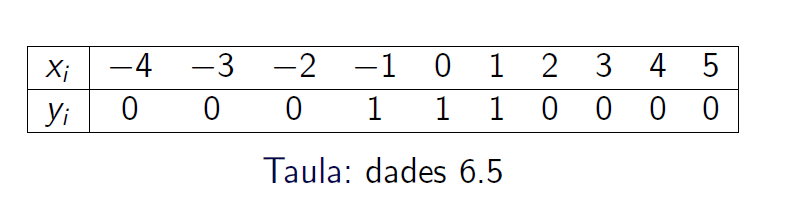

x = -4:5; y = [0 0 0 1 1 1 0 0 0 0];
disp([x; y])

    -4    -3    -2    -1     0     1     2     3     4     5
     0     0     0     1     1     1     0     0     0     0



t = linspace(-4,4,200)

t =    -4.0000   -3.9598   -3.9196   -3.8794   -3.8392   -3.7990   -3.7588   -3.7186   -3.6784   -3.6382   -3.5980   -3.5578   -3.5176   -3.4774   -3.4372   -3.3970   -3.3568   -3.3166   -3.2764   -3.2362   -3.1960   -3.1558   -3.1156   -3.0754   -3.0352   -2.9950   -2.9548   -2.9146   -2.8744   -2.8342   -2.7940   -2.7538   -2.7136   -2.6734   -2.6332   -2.5930   -2.5528   -2.5126   -2.4724   -2.4322   -2.3920   -2.3518   -2.3116   -2.2714   -2.2312   -2.1910   -2.1508   -2.1106   -2.0704   -2.0302


- Del polinomi interpolador

 %polyinterp

- Del spline lineal

 pt = interp1(x,y,t)

pt =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


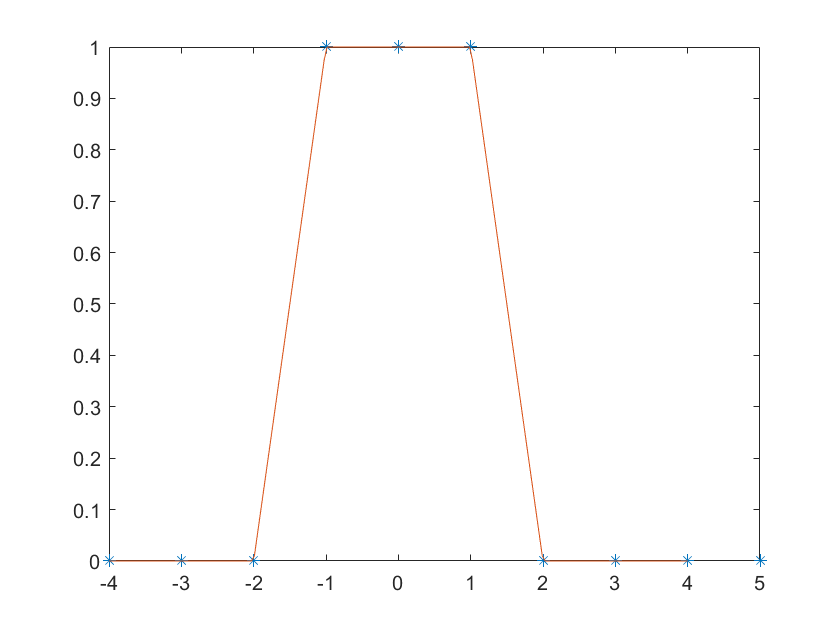

 plot(x,y, '*')
 hold on
 plot(t,pt)
 hold off

- Del spline natural

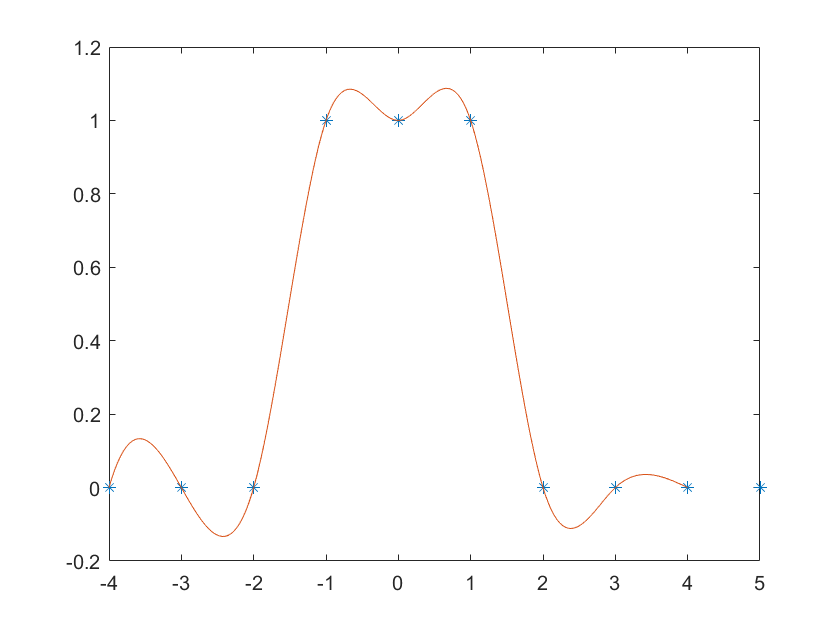

 pt = interp1(x,y,t,'spline');
 plot(x,y, '*')
 hold on
 plot(t,pt)
 hold off

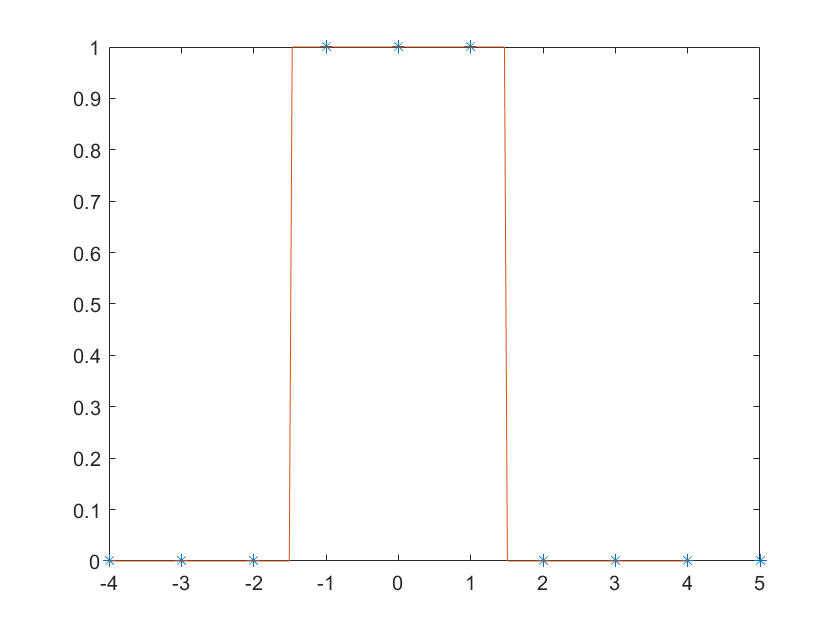

 pt = interp1(x,y,t,'nearest');
 plot(x,y, '*')
 hold on
 plot(t,pt)
 hold off

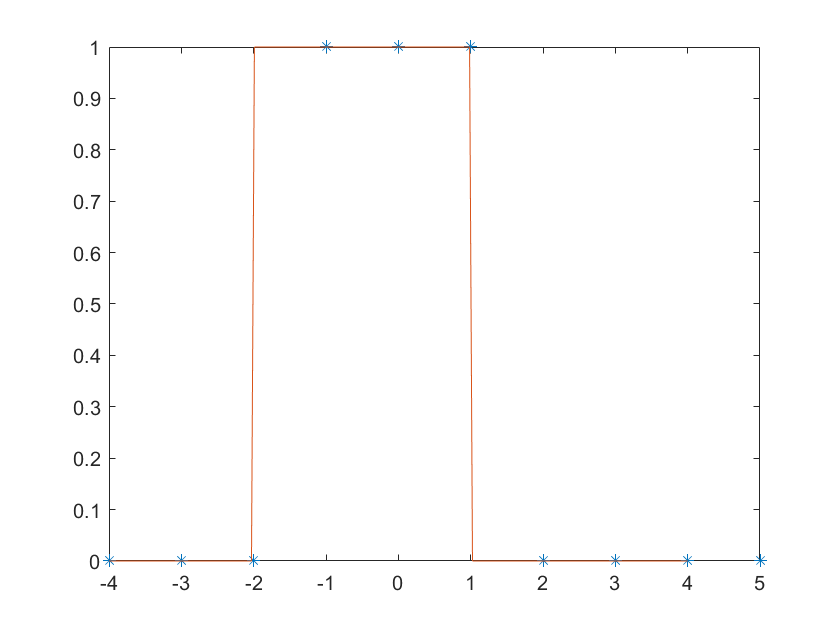

 
 pt = interp1(x,y,t,'next');
 plot(x,y, '*')
 hold on
 plot(t,pt)
 hold off

- Del spline shape-preserving

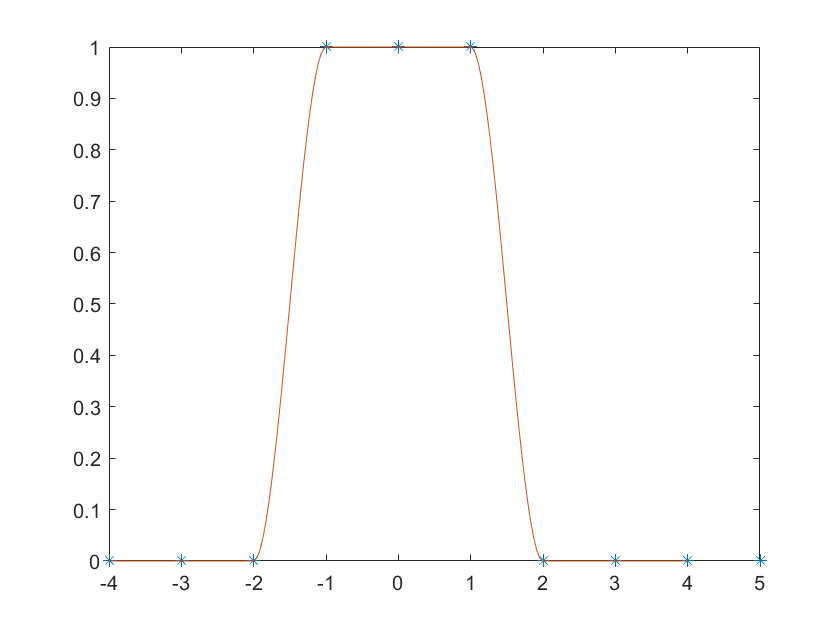

   pt = interp1(x,y,t,'pchip');
 plot(x,y,'*')
 hold on
 plot(t,pt)
 hold off

### Exercici 7

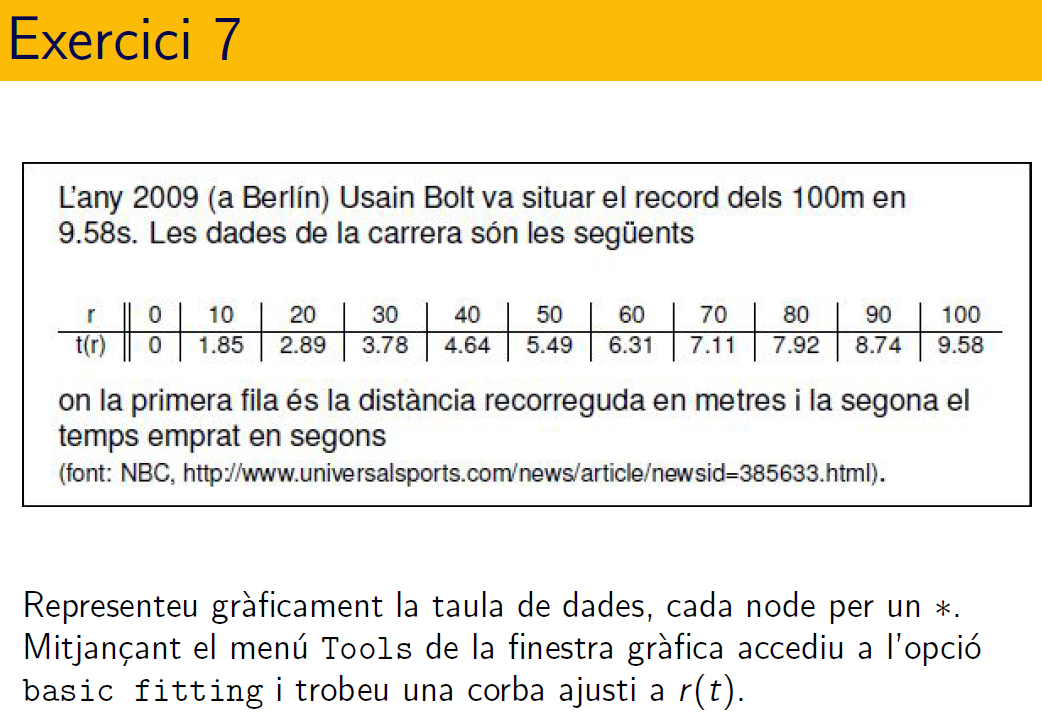

### Exercici 8

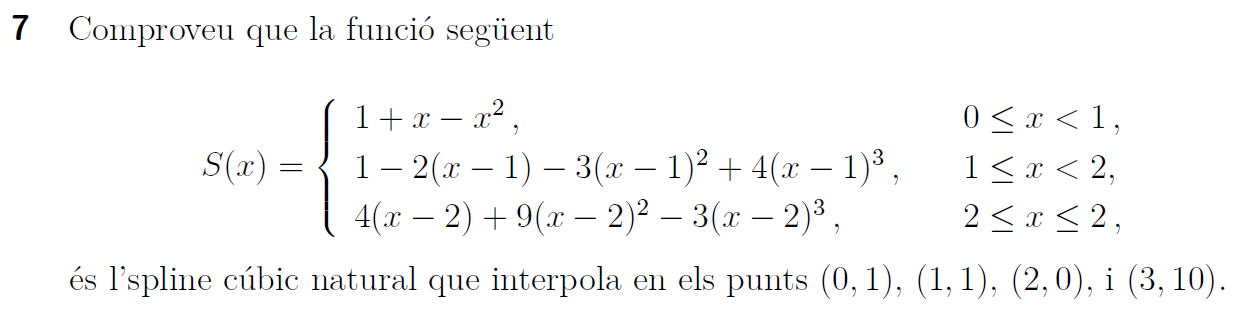

## $\bullet$RECORDEM ... Bloc 3 

### Ajust de dades

### Funció de MATLAB®  

Els coeficients dels polinomis per mínims quadrats es poden obtenir amb polyfit, i els valors aproximats amb polyval. Consulteu [polyfit](https://es.mathworks.com/help/matlab/ref/polyfit.html)

openExample('matlab/FitPolynomialToSetOfPointsExample')

## $\bullet$PRACTIQUEM ....

### Exercici 9

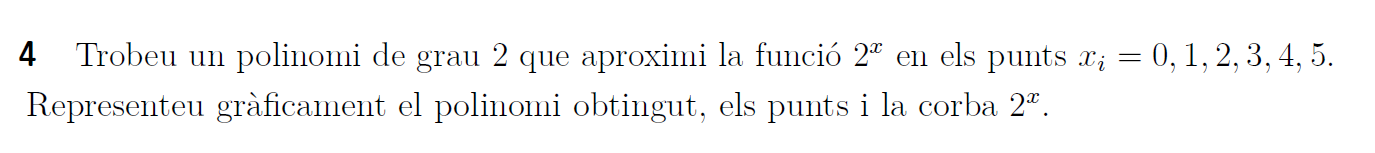

### Exercici 10.   

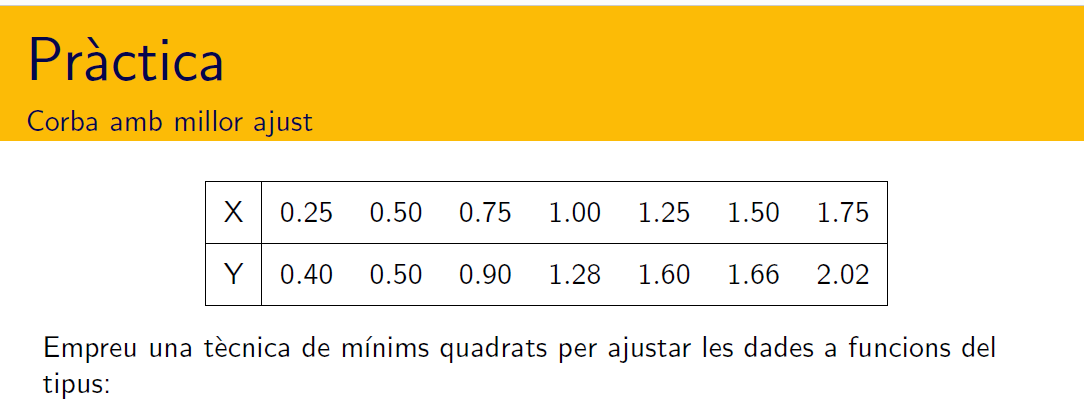

clearvars; clf; format shortG
x = 0.25:0.25:1.75;
y = [0.4,0.5 0.9 1.28 1.60 1.66 2.02];
disp([x;y]')

- recta

- Polinomi de grau 4

- Corba $y = ax^{b}  \rightarrow \ln(y)=b\ln(x)+\ln(a) \rightarrow Y = A_1X+A_0$

- Gràfica

#### Exercici 11.  Sistema  sobredeterminat

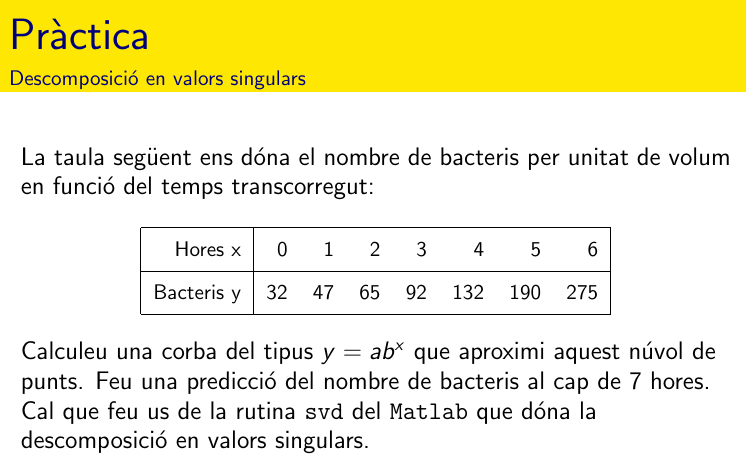

% veure practica5_exercici5

`document preparat per M. Àngela Grau Gotés - maig 2022`